ECE 537 

Exercise #5

Group 5

Muqian Gui ----- V00870654

Hang Ruan ----- V00923058

clc;
clear all;
close all;


dim = 3; % Setdimension as 3 
K1 = 750000;
u1 = [0 ; 0 ; 0]; % Mean for class A
% Prescribed covariance matrix for class A
cov_matrix1 = [3.0184 0.4331 -1.4481; 0.4331 0.9436 -0.6456; -1.4481 -0.6456 1.2880];
data_A = dataGeneratorFunc(dim,K1,u1,cov_matrix1); % Data generated for class A
R_A = mahalDistance(data_A, data_A); % Obtain the dataset with Mahalonobis distance 1<&>2

u2 = randomRow(R_A);% Random select a point form R_A as the mean vector for class B
K2 = 190000;
cov_matrix2 = [0.987 0.123 -0.456; 0.123 1.234 0.345; -0.456 0.345 0.876];
data_B = dataGeneratorFunc(dim,K2,u2,cov_matrix2); % Data generated for class B
R_B = mahalDistance(data_B,R_A); % Obtain the dataset with Mahalonobis distance 1<&>2

u3 = randomRow(R_B);% Random select a point form R_B as the mean vector for class C
K3 = 45000;
cov_matrix3 = [2.345 1.234 0.567; 1.234 3.456 0.789; 0.567 0.789 1.2341];
data_C = dataGeneratorFunc(dim,K3,u3,cov_matrix3); % Data generated for class C
R_C = mahalDistance(data_C, R_B); % Obtain the dataset with Mahalonobis distance 1<&>2

u4 = randomRow(R_C);% Random select a point form R_C as the mean vector for class D
K4 = 12000;
cov_matrix4 = [6.8928 -1.3750 3.1945; -1.3750 3.3572 0.6945; 3.1945 0.6945 3.7500];
data_D = dataGeneratorFunc(dim,K4,u4,cov_matrix4); % Data generated for class D
R_D = mahalDistance(data_D, R_C); % Obtain the dataset with Mahalonobis distance 1<&>2

u5 = randomRow(R_D);% Random select a point form R_D as the mean vector for class E
K5 = 3000;
cov_matrix5 = [6.5 2.1651 1.25 ; 2.1651 5.125 2.3816 ; 1.25 2.3816 2.3750];
data_E = dataGeneratorFunc(dim,K5,u5,cov_matrix5); % Data generated for class E

% plot3(data_A(:,1), data_A(:,2), data_A(:,3),'.')
% hold on
% plot3(data_B(:,1), data_B(:,2), data_B(:,3),'.')
% hold on
% plot3(data_C(:,1), data_C(:,2), data_C(:,3),'.')
% hold on
% plot3(data_D(:,1), data_D(:,2), data_D(:,3),'.')
% hold on
% plot3(data_E(:,1), data_E(:,2), data_E(:,3),'.')


% Q2
matrix = [data_A ; data_B ; data_C ; data_D ; data_E]; % Combine all the data into one dataset
[m,n] = size(matrix); 
% Create the label set for each class, 1-A,2-B,3-C,4-D,5-E
label = [ones(1, 750000), 2*ones(1, 190000), 3*ones(1, 45000), 4*ones(1, 12000), 5*ones(1, 3000)]'; 

indx = randperm(m); % Random number from 1-1000000 in random order
com_data = matrix(indx,:); % Make the dataset in random order
com_label = label(indx,:); % Make the label dataset in the same order
train_data = com_data(1:0.1*m, :); % Take the first 10% of dataset as training data
test_data = com_data(0.1*m+1:end, :); % The rest 90% is the testing data
train_label = com_label(1:0.1*m, :); % create the corresponding label set
test_label = com_label(0.1*m+1:end, :);
indx_train = indx(:,1:0.1*m); 
indx_test = indx(:,0.1*m+1:end);

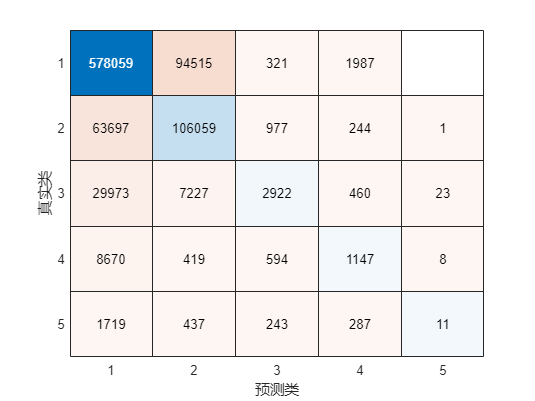

cm =   ConfusionMatrixChart - 属性:

    NormalizedValues: [5×5 double]
         ClassLabels: [5×1 double]

  显示 所有属性


% Q3-Q4
% Bayes

mdl = fitcnb(train_data,train_label );
pre = predict (mdl,test_data);

cm = confusionchart(test_label, pre)

yind_bay = round(pre);
percentErrors_bay = sum(yind_bay ~= test_label)/numel(test_label)

percentErrors_bay = 0.2353

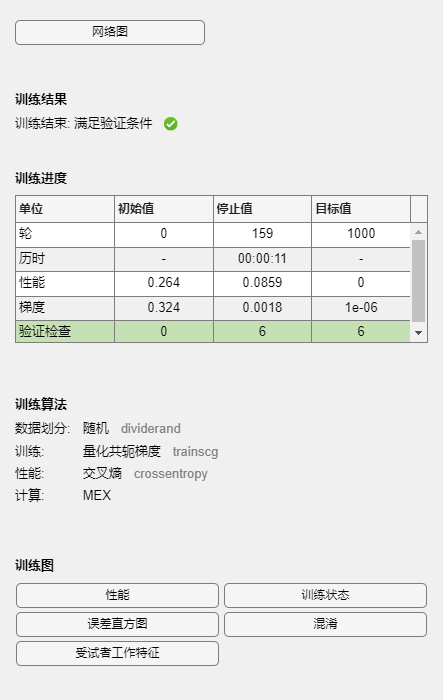


% Neuro Network
% Onehot encoder for label
train_label = (train_label == 1:5)';
test_label = (test_label == 1:5)';

x = train_data';
t = train_label;
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);
[net,tr] = train(net,x,t); % Train the Network

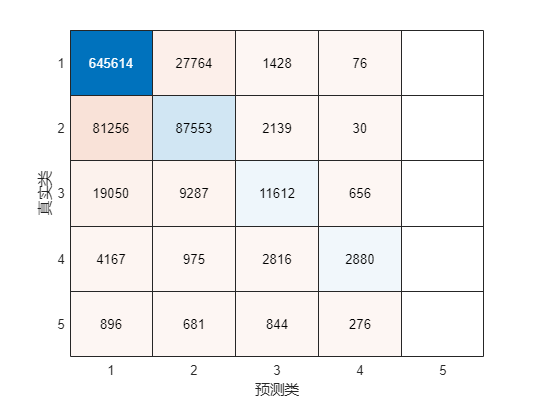

cm_nn =   ConfusionMatrixChart - 属性:

    NormalizedValues: [5×5 double]
         ClassLabels: [5×1 double]

  显示 所有属性


y = net(test_data'); % Predicted value from Neuro Network
yind = vec2ind(y); % Round to ind
% yind = round(y);
% yind = vec2ind(yind);
tind = vec2ind(test_label);

cm_nn = confusionchart(tind', yind')

percentErrors = sum(yind ~= tind)/numel(tind)

percentErrors = 0.1693

Q5

For both training and testing performance for the classifiers, they will be less sensitive to the class which with less number of examples. Because compare with the majority classes, the sample numbers of minority class are way less for classifier to capture the feature. And also, because of the inbalanced datasets, the classifiers are all less robust, all of them will predict towrd to the majority classes. The ability of handling unseen minority class will be poor. For Bayes classifier, it might perform good on training set. But it will not able to perform good on testing set if the classes are not well seperate.In this case, there are a lot of overlaping for classes, so it's hard to predict correctly. If the class features are well seperated, Even the dataset is unbalanced, Bayes should still have a good performance since it's prediction is mainly depending on the class distribution and conditional probabilities. For the neural network classifier, the performance will not that good, because they prefer to predict the data as the majority classes rathern than minority classes.

Based on the results obtained here. Even the percentError from Neural network is lower than Bayes, but actuall Bayes-like approaches still more robust to unbalanced data sets. It's easy to tell from confusion matrix, The one from Bayes still can make some correct prediction on minority classes. But the one from Neural network predict zero correct for class E. Which means it has a bais towrads to the majority classes to ensure a high overall performance. That's why it has lower percentError. Therefor, percentError can't conclude the performance of classifiers with unbalanced datasets. For this case, it might be better using the precision, recall or ROC curve to do the evaluation rather than simply calculating the percentError.

Q6

With simple selecting random draws from unbalanced datasets, the probability of selecting a sample from a certain class will be related to the number of samples for this class in the whole dataset. if more samples of one class in the dataset, there will be more samples form this class being selected into the training set. For example, the class E only have 3000 samples wihin a 1000000 samples dataset and when plan to take 10% for training, the expected number of samples selected from class E will be 0.1*1000000*3000/1000000 which is 300. 

Binomial distribution can be used to model the likelihood of drawing samples into training set. For 99% confidence interval, it's about 2.58 standard deviations of the mean. Therefor, the possible drawns range will be mean +/- 2.58 standard deviation. The possibel draws from class E will be affected when the size changed. As the size of E increases, which means the standard deviation will decreases, so the possible range will be smaller than before which means the ranges being narrow. Oppositely, when the size of E decreases, the standard deviation will be larger so the possible ranges will be bigger than beofre which means it will be wider. 

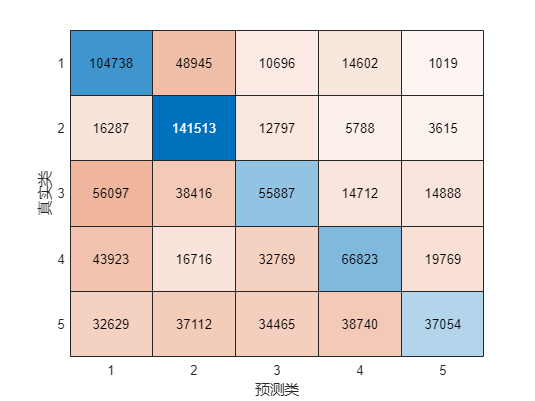

cm_bay_bal =   ConfusionMatrixChart - 属性:

    NormalizedValues: [5×5 double]
         ClassLabels: [5×1 double]

  显示 所有属性


% Q7
% Generate the five classes with 200000 points for each class to make it balance
Kb1 = 200000;
Kb2 = 200000;
Kb3 = 200000;
Kb4 = 200000;
Kb5 = 200000;
data_A_bal = dataGeneratorFunc(dim,Kb1,u1,cov_matrix1); % Data generated for class A
data_B_bal = dataGeneratorFunc(dim,Kb2,u2,cov_matrix2); % Data generated for class B
data_C_bal = dataGeneratorFunc(dim,Kb3,u3,cov_matrix3); % Data generated for class C
data_D_bal = dataGeneratorFunc(dim,Kb4,u4,cov_matrix4); % Data generated for class D
data_E_bal = dataGeneratorFunc(dim,Kb5,u5,cov_matrix5); % Data generated for class E
% Create the label for each class
label_A = ones(1,200000);
label_A = label_A';
label_B = 2*ones(1,200000);
label_B = label_B';
label_C = 3*ones(1,200000);
label_C = label_C';
label_D = 4*ones(1,200000);
label_D = label_D';
label_E = 5*ones(1,200000);
label_E = label_E';
% Random pick 10% data as training data from each class 
rand_indices = randperm(200000, 20000);
remaining_indices = setdiff(1:200000, rand_indices);
% Random 10% from class A as training data and rest for testing
train_A = data_A_bal(rand_indices, :);
train_A_label = label_A(rand_indices, :);
test_A = data_A_bal(remaining_indices,:);
test_A_label = label_A(remaining_indices,:);
% Random 10% from class B as training data and rest for testing
train_B = data_B_bal(rand_indices, :);
train_B_label = label_B(rand_indices, :);
test_B = data_B_bal(remaining_indices,:);
test_B_label = label_B(remaining_indices,:);
% Random 10% from class C as training data and rest for testing
train_C = data_C_bal(rand_indices, :);
train_C_label = label_C(rand_indices, :);
test_C = data_C_bal(remaining_indices,:);
test_C_label = label_C(remaining_indices,:);
% Random 10% from class D as training data and rest for testing
train_D = data_D_bal(rand_indices, :);
train_D_label = label_D(rand_indices, :);
test_D = data_D_bal(remaining_indices,:);
test_D_label = label_D(remaining_indices,:);
% Random 10% from class E as training data and rest for testing
train_E = data_E_bal(rand_indices, :);
train_E_label = label_E(rand_indices, :);
test_E = data_E_bal(remaining_indices,:);
test_E_label = label_E(remaining_indices,:);
% Combine all the training data & correspond label together
train_bal = [train_A;train_B;train_C;train_D;train_E];
train_lab_bal = [train_A_label;train_B_label;train_C_label;train_D_label;train_E_label];
% Combine all the testing data & correspond label together
test_bal = [test_A;test_B;test_C;test_D;test_E];
test_lab_bal = [test_A_label;test_B_label;test_C_label;test_D_label;test_E_label];

% Make all the classes in the combined dataset in a random order
[m_train,n_train] = size(train_bal); 
[m_test,n_test] = size(test_bal); 

indx_t = randperm(m_train);
indx_s = randperm(m_test);
 
train_balance = train_bal(indx_t,:);
train_label_bal = train_lab_bal(indx_t,:);
test_balance = test_bal(indx_s,:);
test_label_bal = test_lab_bal(indx_s,:);

% Apply Bayes on balance data
mdl_bal = fitcnb(train_balance,train_label_bal );
pre_bal = predict (mdl_bal,test_balance);

cm_bay_bal = confusionchart(test_label_bal, pre_bal)

yind_bay = round(pre_bal);
percentErrors_bay = sum(yind_bay ~= test_label_bal)/numel(test_label_bal)

percentErrors_bay = 0.5489

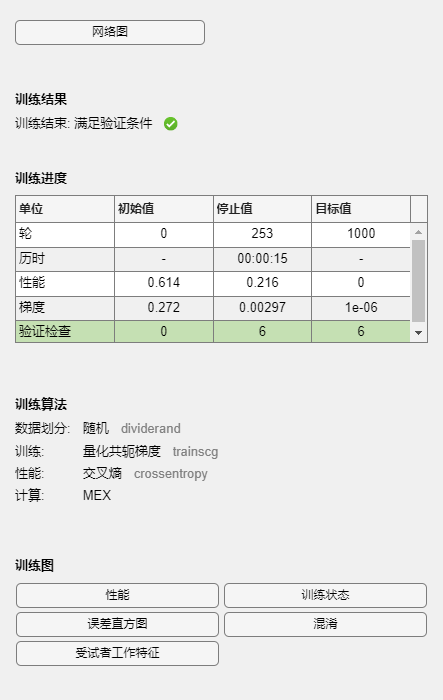


% Apply Neuro Network on balance data
% Onehot encoder for label
train_label_bal = (train_label_bal == 1:5)';
test_label_bal = (test_label_bal == 1:5)';

x = train_balance';
t = train_label_bal;
trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize, trainFcn);
[net,tr] = train(net,x,t); % Train the Network

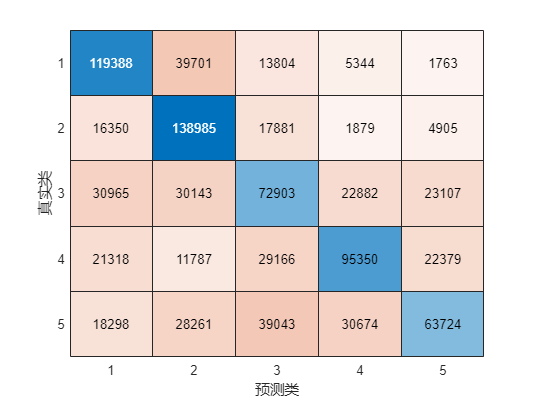

cm_nn_bal =   ConfusionMatrixChart - 属性:

    NormalizedValues: [5×5 double]
         ClassLabels: [5×1 double]

  显示 所有属性


y_bal = net(test_balance'); % Predicted value form Neuro Network
yind_bal = vec2ind(y_bal); % Round to ind
tind_bal = vec2ind(test_label_bal);

cm_nn_bal = confusionchart(tind_bal', yind_bal')

percentErrors = sum(yind_bal ~= tind_bal)/numel(tind_bal)

percentErrors = 0.4552

Comparing to the performance using the imbalanced dataset, both our models achieved a lower accuracy. It's likely due to the increase in the sizes of minority classes. When classifying the imbalanced class, models can get good accuracy by simply predicting everything as class 1 to get 75% accuracy. With the balanced dataset, models need to differentiate classes of equal size that contains lots of overlaps. Models cannot favor one class over the other to improve accuracy.

8. When dealing with an imbalanced dataset, we can take the approach of undersampling where we reduce the size of the abundant class by randomly selecting an equal number of samples to the rare class. On the other hand, we also increase the size of the rare classes by bootstrapping. We can assign weights differently accordingly to their distributions to favour the minority class. It’s also encouraged to explore further into features that distinguish the classes. When evaluating the model, we can look into precision and recall other than accuracy. Finally, stratified cross-validation can be used to ensure equal class distribution in each fold.

9. I think imbalanced data sets in real-world problems can be easily identified in supervised learning. One can count the number of each class by taking the sum of all occurrences for each label. In problems of unsupervised learning, unbalanced data can be troublesome to find without knowing the labels.

It is important to quantify the degree to which it is unbalanced. Many approaches dealing with imbalanced datasets need the extent of imbalance and domain-specific knowledge to work. When knowing the labels and having sufficient samples, we can calculate the number of samples for each class in order to find the degree of imbalance. But it’s difficult to classify it in the case of unsupervised learning. Given imbalance data can occur in a multi-class scenario where a single class sample ratio is not sufficient to tell the degree of imbalance, I would use an equation that penalizes any minority class in a dataset. We divide the total number of samples by the number of classes. Any class that has a number different number of samples gets penalized for a score and the sum for all classes can be used as a way to classify the degree of data imbalancement. 

The balance or unbalanced nature of a given data set can change. They’re usually defined according to the currently available data. As you see more, the distribution of class can change.

When you collect more data, the minority class can get more samples for models to learn. And it’s also possible for the majority class to completely overtake the new samples to worsen the imbalance in the dataset

function R = mahalDistance(data1, data2)
distances = mahal(data1, data2);
[m n]= size(distances);
result = [];
for i = 1:m
if distances(i) > 1 && distances(i) < 2
        % Add the element to the result array
        result = [result, i];
    end
end
R = data1(result,:);
end

function u = randomRow(R)
numRows = size(R, 1);
randomIndex = randi(numRows);
u = R(randomIndex, :);
u = u';
end

function data = dataGeneratorFunc(dim,K,u,cov_matrix)
    data = randn(K,dim);
    data = data-mean(data,1);
    data = data/chol(cov(data));
    data = data*chol(cov_matrix); 
    data = data+u';
end